clc;clear;
city_pos = [10,10;
    2,1;
    20,10;
    10,20;
    1,10;
    4,5;
    10,3;
    14,7;
    6,16;
    13,19;
    19,18];
cmap = [1 1 1;...  % 1-白色-空地
    0 0 0;...  % 2-黑色-障碍物
    0 1 1;...  % 3-青蓝色-start_pos
    1 0 0;...  % 4-红色-goal_pos
    0 1 0;...  % 5-绿色-stop_pos
    0 0 1;...  % 6-蓝色 TSP1路径
    1 1 0;...  % 7-黄色 TSP2路径
    1 0 1];...  % 8-品红色 TSP3路径
TSP_path = load("TSP_path.mat");
path1 = TSP_path.path_best1;
path2 = TSP_path.path_best2;
path3 = TSP_path.path_best3;
clear TSP_path
Grid = load("map.mat");
Grid = Grid.ans;


row_grid = size(Grid,1);
col_grid = size(Grid,2);
numb_grid = row_grid*col_grid;
startPos = sub2ind([size(Grid,1),size(Grid,2)],10,10);
goalPos1 = 2;
goalPos2 = sub2ind([size(Grid,1),size(Grid,2)],20,10);
goalPos3 = sub2ind([size(Grid,1),size(Grid,2)],10,20);
goalPos = [goalPos1,goalPos2,goalPos3];
Grid(startPos) = 3;
Grid(goalPos) = 5;
stopPos1 = sub2ind([size(Grid,1),size(Grid,2)],1,10);
stopPos2 = sub2ind([size(Grid,1),size(Grid,2)],4,5);
stopPos3 = sub2ind([size(Grid,1),size(Grid,2)],10,3);
stopPos4 = sub2ind([size(Grid,1),size(Grid,2)],14,7);
stopPos5 = sub2ind([size(Grid,1),size(Grid,2)],6,16);
stopPos6 = sub2ind([size(Grid,1),size(Grid,2)],13,19);
stopPos7 = sub2ind([size(Grid,1),size(Grid,2)],19,18);
stopPos = [stopPos1,stopPos2,stopPos3,stopPos4,stopPos5,stopPos6,stopPos7];
Grid(stopPos) = 5;
path_index = [startPos,goalPos1,goalPos2,goalPos3...
    stopPos1,stopPos2,stopPos3,stopPos4,stopPos5...
    stopPos6,stopPos7];
path1 = path_index(path1);
path2 = path_index(path2);
path3 = path_index(path3);

TSP1_path = [];
tic
for i = 1:length(path1)-1
    [dist_best, path_best, per_iter_best,per_iter_avg] = improvedEtaACA(Grid,path1(i),path1(i+1));
    fisrt_inf_ind = find(isinf(path_best(1,:)),1);
    path_best = path_best(1:fisrt_inf_ind-1);
    if i == length(path1)-1
        TSP1_path = [TSP1_path,path_best(1:end)];
    else
        TSP1_path = [TSP1_path,path_best(1:end-1)];
    end
end
toc

历时 9.947708 秒。


%记录TSP1最佳路径
path_best1 = TSP1_path;
TSP1_path(ismember(TSP1_path,path_index)) = [];
Grid(TSP1_path) = 6;

TSP2_path = [];
tic
for i = 1:length(path2)-1
    [dist_best, path_best, per_iter_best,per_iter_avg] = improvedEtaACA(Grid,path2(i),path2(i+1));
    fisrt_inf_ind = find(isinf(path_best(1,:)),1);
    path_best = path_best(1:fisrt_inf_ind-1);
    if i == length(path2)-1
        TSP2_path = [TSP2_path,path_best(1:end)];
    else
        TSP2_path = [TSP2_path,path_best(1:end-1)];
    end
end
toc

历时 13.746035 秒。


%记录TSP1最佳路径
path_best2 = TSP2_path;
TSP2_path(ismember(TSP2_path,path_index)) = [];
Grid(TSP2_path) = 6;

TSP3_path = [];
tic
for i = 1:length(path3)-1
    [dist_best, path_best, per_iter_best,per_iter_avg] = improvedEtaACA(Grid,path3(i),path3(i+1));
    fisrt_inf_ind = find(isinf(path_best(1,:)),1);
    path_best = path_best(1:fisrt_inf_ind-1);
    if i == length(path3)-1
        TSP3_path = [TSP3_path,path_best(1:end)];
    else
        TSP3_path = [TSP3_path,path_best(1:end-1)];
    end
end
toc

历时 16.552760 秒。


%记录TSP1最佳路径
path_best3 = TSP3_path;
TSP3_path(ismember(TSP3_path,path_index)) = [];
Grid(TSP3_path) = 6;

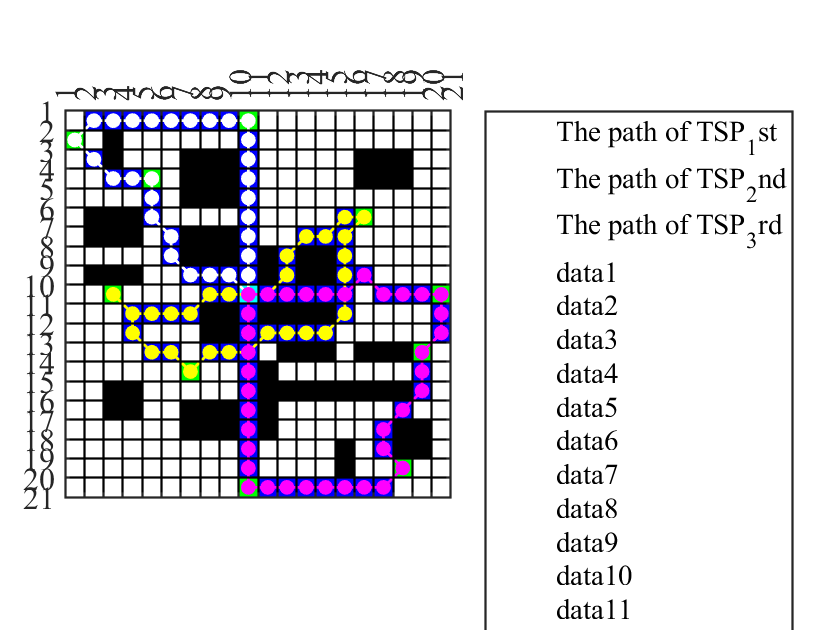


colormap(cmap)
image(1.5,1.5,Grid)
grid on;
set(gca,'gridline','-','GridColor','k','LineWidth',2,'GridAlpha',1);
set(gca,'XTick',1:21,'YTick',1:21);
axis image
set(gca,'xAxisLocation','top');
set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')
hold on;
for i = 1:length(path_best1)-1
    [coord1_x,coord1_y] = ind2sub([row_grid,col_grid],path_best1(i));
    [coord2_x,coord2_y] = ind2sub([row_grid,col_grid],path_best1(i+1));
    h1 = plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'ow-', 'linewidth', 1.4, 'linestyle','-','Color','w','markerfacecolor', 'w');
    %这里的coord1_x应该是对应的y
end
for i = 1:length(path_best2)-1
    [coord1_x,coord1_y] = ind2sub([row_grid,col_grid],path_best2(i));
    [coord2_x,coord2_y] = ind2sub([row_grid,col_grid],path_best2(i+1));
    h2 = plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'oy-', 'linewidth', 1.4, 'linestyle','-','Color','y','markerfacecolor', 'y');
    %这里的coord1_x应该是对应的y
end
for i = 1:length(path_best3)-1
    [coord1_x,coord1_y] = ind2sub([row_grid,col_grid],path_best3(i));
    [coord2_x,coord2_y] = ind2sub([row_grid,col_grid],path_best3(i+1));
    h3 = plot([coord1_y,coord2_y]+0.5,[coord1_x,coord2_x]+0.5,'om-', 'linewidth', 1.4, 'linestyle','-','Color','m','markerfacecolor', 'm');
    %这里的coord1_x应该是对应的y
end

% hh = legend('The path of 1stTSP','The path of 2ndTSP','The path of 3rdTSP')
% hh.Location = 'bestoutside';
% set(gca, 'linewidth', 1.1, 'fontsize', 16, 'fontname', 'times')